% Input the data file 

tname='desalination_test_1'; % input the .txt filename
 
mass_g_data = readtable(tname); % create a table from the data (weight in grams)

% Calculate flux 

A_membane = 0.0163; % meters^2

liters_data = mass_g_data{:,1}*0.001; % grams to liters conversion 

total_time = find(liters_data==liters_data(end,:))*0.000277778 % hours

total_time = 0.8750


total_liters = liters_data(end) - liters_data(1,:)

total_liters = 0.1255


calculated_flux = total_liters/A_membane/total_time % liters/meter^2/hour

calculated_flux = 8.7993

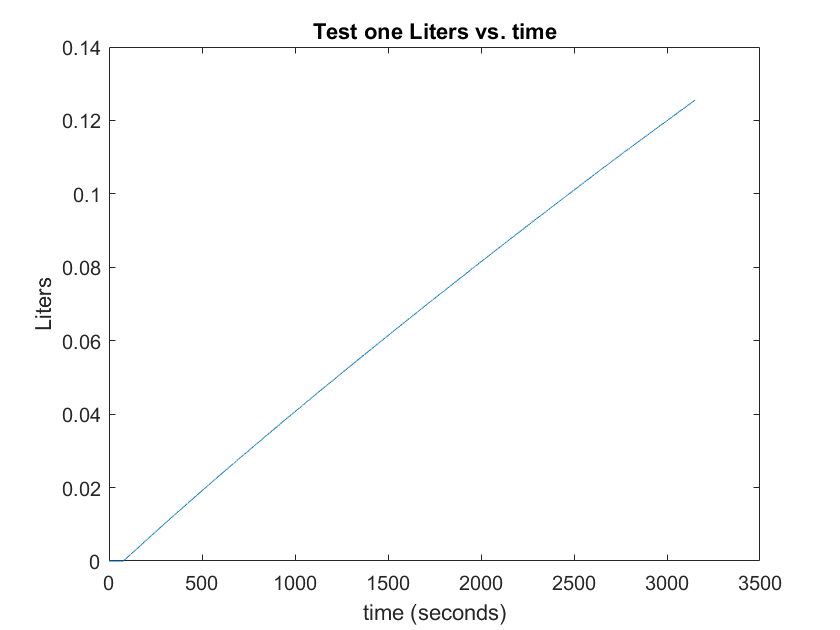

% Plot Liters over time 

plot(liters_data)
title('Test one Liters vs. time')
xlabel('time (seconds)')
ylabel('Liters')

% calculate permeability

osmotic_pressure = 0.105 * 1.01325; % converts from atm to barg
area = 0.8; % m^2
P = 300 * 0.0689476; % pressure, converts from psi to barg
Jw = (50 * 3.78541 * (1 / 24)) / area % flux, converts from gpd to lmh

Jw = 9.8578


A = Jw / (P - osmotic_pressure) % permeability, lmh/barg

A = 0.4791